# Presenting multiple signals

Copyright (C) 2022  Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIOVASCULAR AND RESPIRATORY MONITORING DEVICES

## Presenting ECG and SCG signals

We present ECG lead 1 signal and a signal collected by an accelerometer placed on the chest

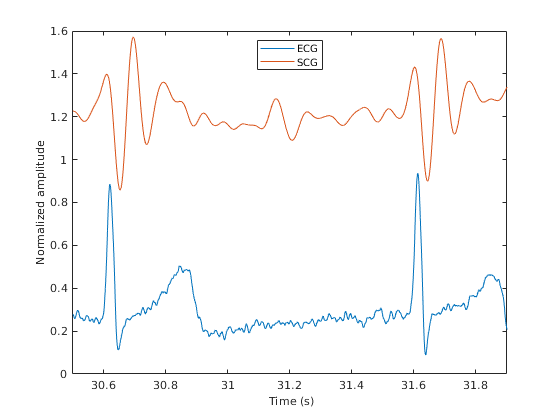


sig=readtable('sync_biomed_20201020_br12.csv');
figure
fs=8008;
T=1/fs;
t=T:T:length(sig.ECG)*T;

plot(t,rescale1(sig.ECG))
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Normalized amplitude', 'FontSize', 10)




% Filter SCG_z in the range of 0.47 Hz and 16 Hz using Wavelet
% decomposition
levelForReconstruction = [false, false, false, false, false, false, false, false, true, true, true, true, true, false, false, false, false];
% Perform the decomposition using modwt
wt = modwt(sig.SCG_Z, 'sym4', 16);
% Construct MRA matrix using modwtmra
mra = modwtmra(wt, 'sym4');
% Sum along selected multiresolution signals
a1 = sum(mra(levelForReconstruction,:),1);

hold on
plot(t,rescale1(a1')+0.7)

legend("ECG","SCG","Location","north");
xlim([30.5,31.9])
exportgraphics(gcf,"Fig10.3.jpg", 'Resolution',600)